# Processing of Experimental Data 

clear all
clc

## Import Data

A=importdata('sample.dat');     % read accelerometer output data file
D=A.data;

## Data Visualisation

Time=D(:,1);                    % Time is the first column
a0=D(:,4);                      % For this analysis we take the sceond column of data values only
dt=(Time(2)-Time(1));
Fs=1/dt;                        % Sampling frequency
a0 = a0 - mean(a0)

a0 =     0.0204
    0.0152
    0.0204
    0.0409
    0.0460
    0.0511
    0.0306
    0.0460
    0.0255
    0.0204


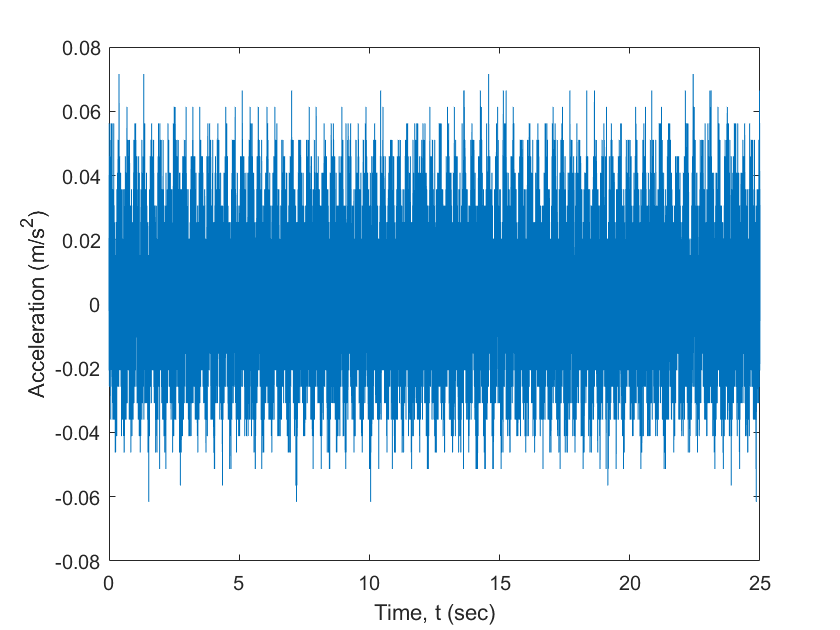


figure (1)                      % Plot of acceleration vs time
plot(Time,a0)
ylabel('Acceleration (m/s^2)')
xlabel('Time, t (sec)')

## Filtering

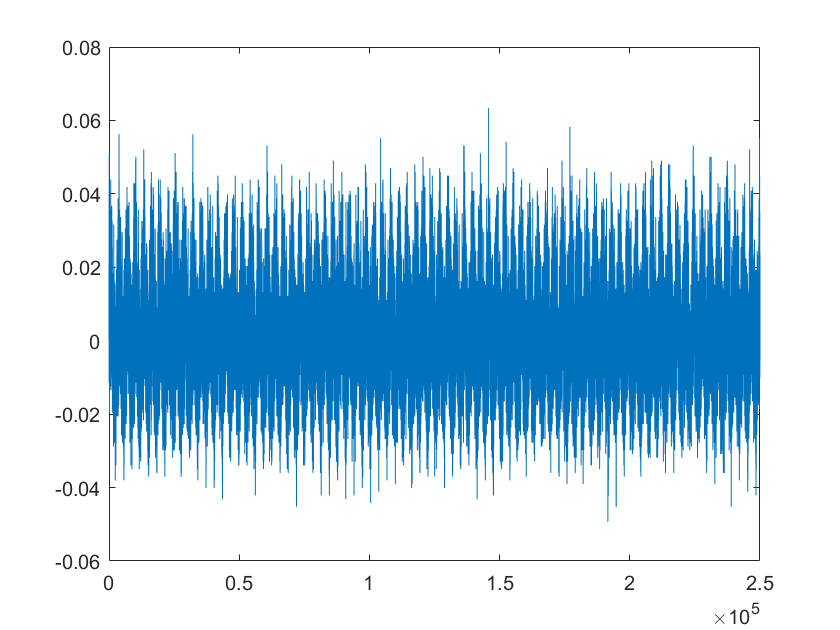

x0_filtered=smooth(a0);
figure
plot(x0_filtered)

## Windowing

signal=x0_filtered;                 % Signal of interest (for which FFT has to be taken)
L=length(signal);
w = hann(L);                        % Hanning window
x1=signal.*w;

## FFT

X1 = fft(x1)/(L/2);
X1 = X1(1:L/2);
mx1 = abs(X1);                      % Take the magnitude of fft of x

f = linspace(0,Fs/2,L/2)

f = 	1.0e+03 *

         0    0.0000    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0010    0.0010    0.0010    0.0011    0.0011    0.0012    0.0012    0.0012    0.0013    0.0013    0.0014    0.0014    0.0014    0.0015    0.0015    0.0016    0.0016    0.0016    0.0017    0.0017    0.0018    0.0018    0.0018    0.0019    0.0019    0.0020


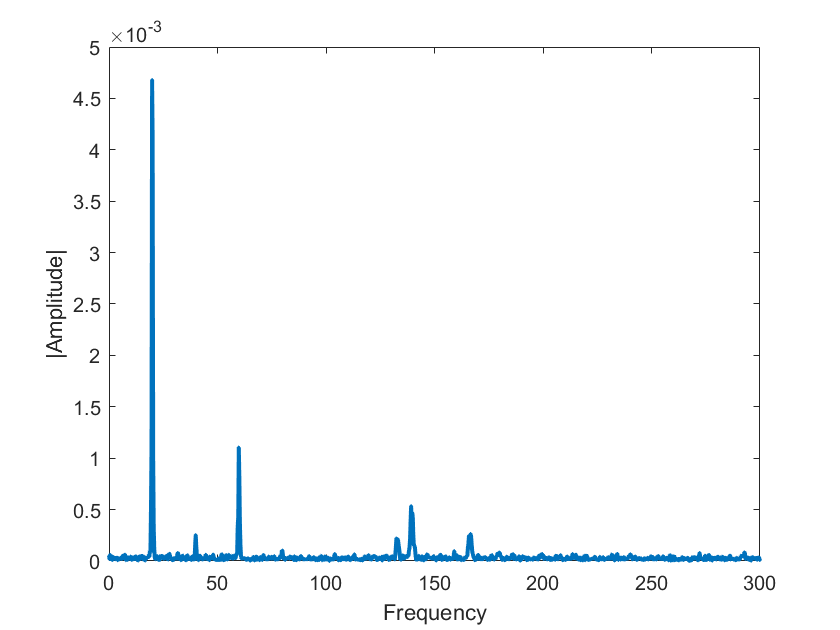


figure                          % Plotting
plot(f*(2*pi),(mx1),'LineWidth',2);               % Convert Hz to radians
xlabel('Frequency')
ylabel('|Amplitude|')
xlim([0 300])